Save (saveOrLoad = 0) or load (saveOrLoad = 1) the workspace with all the variables for (futher) testing.

clc; clear; close all;
saveOrLoad = 1; 

%Create a timestamp string in the format YYYYMMDD_HHMMSS
timestamp = datestr(datetime('now'), 'yyyymmdd_HHMMSS'); 
filename = ['my_workspace_' timestamp '.mat'];  % Construct filename
filename = 'my_workspace_20260115_181543.mat';

if ~saveOrLoad
   save(filename);
else
   load(filename);
end

## Related Techniques

This section demonstrates how to implement some relevant techniques in MATLAB, such as beamforming [1-2], direction of arrival estimation [5], and speaker separation [6-7]. For speech denoising using deep learning networks, please refer to [8].

### Direction of Arrival Estimation -[Notebook lm](https://notebooklm.google.com/notebook/f519718b-e4db-4716-af42-78c925643d0c)

Use direction-of-arrival (DOA) estimation to localize the direction of a radiating or reflecting source [5].

**GCC Estimator**

The [`phased.GCCEstimator`](https://www.mathworks.com/help/phased/ref/phased.gccestimator-system-object.html) System object™ creates a direction of arrival estimator for wideband signals. This System object estimates the direction of arrival or time of arrival among sensor array elements using the generalized cross-correlation with phase transform algorithm (GCC-PHAT) . You can estimate the broadside arrival angle ([Broadside Angles](https://www.mathworks.com/help/phased/ug/spherical-coordinates.html)) of the plane wave with respect to the line connecting the two microphones. 

gcc_estimator = phased.GCCEstimator('SensorArray',micULA,...
    'PropagationSpeed',c,'SampleRate',fs);

Use the `GCCEstimator to estimate the` direction-of-arrival in two Tasks.

anechoic_combined_doa = gcc_estimator(anechoic_rcv_noisy')

anechoic_combined_doa = 39.4267

### Beamforming

Beamformers enhance detection of signals by coherently summing signals across elements of arrays. Conventional beamformers have fixed weights while adaptive beamformers have weights that respond to the environment. Use adaptive beamformers to reject spurious or interfering signals from non-target directions. The Phased Array System toolbox supports narrowband and wideband beamformers [2].

**Time Delay Beamformer**

The [`phased.TimeDelayBeamformer`](https://www.mathworks.com/help/phased/ref/phased.timedelaybeamformer-system-object.html) System object™ object implements a time delay beamformer. The object performs delay and sum beamforming on the received signal by using time delays.

td_beamformer = phased.TimeDelayBeamformer('SensorArray',micULA,...
    'PropagationSpeed',c,'SampleRate',fs,'Direction',target_angles');

td_bf_anechoic = td_beamformer(anechoic_rcv_noisy');
soundsc(td_bf_anechoic(1:num_play_samples)',fs)

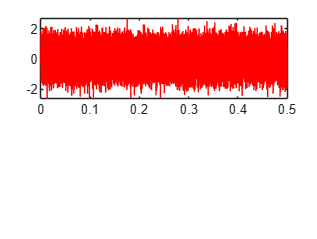

%% 1. Setup Parameters
fs = 44100;                 % Sampling frequency
c = 343;                    % Speed of sound
f_signal = 1000;            % Frequency of our test tone
t = (0:1/fs:0.5)';          % 0.5 seconds of audio
target_angle = 30;          % Where the "voice" is coming from (Degrees)

% Define the Array (2 Microphones, 5cm apart)
mic_spacing = 0.05; 
micULA = phased.ULA('NumElements', 2, 'ElementSpacing', mic_spacing);

%% 2. Create the Noisy Signal
% Create a steering vector for the target angle
steerVec = phased.SteeringVector('SensorArray', micULA, 'PropagationSpeed', c);
sv = steerVec(f_signal, target_angle);

% Simulate the signal hitting 2 mics with a slight delay/phase difference
clean_signal = sin(2*pi*f_signal*t);
micsig = clean_signal * sv'; % This creates a [Samples x 2] matrix

% Add some random noise to each microphone
micsig_noisy = micsig + 0.5*randn(size(micsig));

%% 3. Apply Time Delay Beamforming
% Initialize the beamformer
td_beamformer = phased.TimeDelayBeamformer('SensorArray', micULA, ...
    'PropagationSpeed', c, 'SampleRate', fs, 'Direction', [target_angle; 0]);

% Run the beamformer
% Input: [Samples x Channels] -> Output: [Samples x 1]

beamformed_out = td_beamformer(anechoic_rcv_noisy');

%% 4. Visualization (The "Workable" Part)
figure('Color', 'w', 'Position', [100, 100, 800, 600]);

% Plot 1: The Input vs Output signals
subplot(2,1,1);
plot(t, micsig_noisy(:,1), 'r', 'DisplayName', 'Mic 1 (Noisy)'); hold on;

plot(t, beamformed_out, 'b', 'LineWidth', 1.5, 'DisplayName', 'Beamformed Output');

Error using plot
Specify the coordinates as vectors or matrices of the same size, or as a vector and a matrix that share the same length in at least one dimension.

xlim([0 0.01]); % Zoom in to see the waveforms
title('Time Domain: Noisy Input vs. Cleaned Output');
xlabel('Time (s)'); ylabel('Amplitude');
legend; grid on;

% Plot 2: The "Beam" (Spatial Response)
% This shows where the microphones are "listening"
subplot(2,1,2);
pattern(micULA, f_signal, -180:180, 0, 'PropagationSpeed', c, ...
    'Type', 'directivity', 'CoordinateSystem', 'polar');
title(['Spatial Response (Pointed at ', num2str(target_angle), '°)']);

### Speaker Seperation

#### Load a Pretrained Model

Execute the following commands to download and unzip a pretrained speaker separation model [`separateSpeakers`](https://ww2.mathworks.cn/help/audio/ref/separatespeakers.html) to your temporary directory.   

%downloadFolder = fullfile(tempdir,"separateSpeakerDownload");
%loc = websave(downloadFolder,"https://ssd.mathworks.com/supportfiles/audio/separateSpeakers.zip");
%modelsLocation = tempdir;
%unzip(loc,modelsLocation)
%addpath(fullfile(modelsLocation,"separateSpeakers"))
%addpath(fullfile(pwd,"separateSpeakers"))

addpath(fullfile("separateSpeakers"))
addpath(fullfile(pwd,"separateSpeakers"))

#### **Method 1: Use separateSpeakers and then Combine Signals** [**NotebookLM**](https://notebooklm.google.com/notebook/49228b36-4f58-46ab-97f5-b83e99f2115f)

**Anechoic Chamber**

Use the pre-trained speaker separation model to seperate target and interference signals at the two microphone elements respectively:

anechoic_mic1_out = separateSpeakersTest(anechoic_rcv_noisy(1,:),signal_length,fs);
anechoic_mic2_out = separateSpeakersTest(anechoic_rcv_noisy(2,:),signal_length,fs);

Calulate the average signal:

anechoic_avg_out = (anechoic_mic1_out + anechoic_mic2_out)/2;

false
soundsc(anechoic_avg_out(1:num_play_samples,target_id)',fs)
%soundsc(anechoic_avg_out(1:num_play_samples,interf_id)',fs)

Estimate the DoA: the broadside-reference arrival angle ([Broadside Angles](https://www.mathworks.com/help/phased/ug/spherical-coordinates.html)) measured from the array normal.

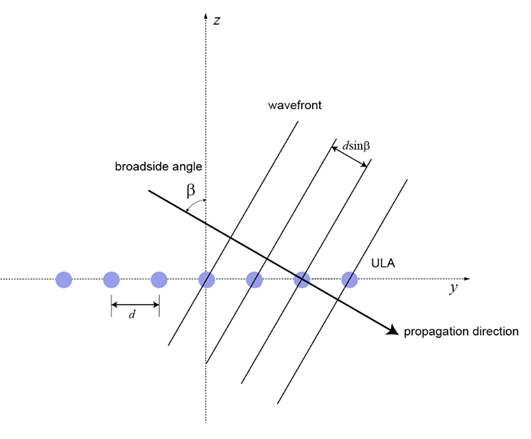

anechoic_target_doa = gcc_estimator([anechoic_mic1_out(:,target_id) anechoic_mic2_out(:,target_id)]) % true value: 0 degree
anechoic_interf_doa = gcc_estimator([anechoic_mic1_out(:,interf_id) anechoic_mic2_out(:,interf_id)]) % true value: 50 degree

**Reverberant Room** 

Use the pre-trained speaker separation model to seperate target and interference signals at the two microphone elements respectively:

% reverb_mic1_out = separateSpeakersTest(reverb_rcv_noisy(1,:),signal_length,fs);
% reverb_mic2_out = separateSpeakersTest(reverb_rcv_noisy(2,:),signal_length,fs);

Calulate the average signal:

% reverb_avg_out = (reverb_mic1_out + reverb_mic2_out)/2;
% soundsc(reverb_avg_out(1:num_play_samples,target_id)',fs)
% soundsc(reverb_avg_out(1:num_play_samples,interf_id)',fs)

Estimate the DoA: the broadside-reference arrival angle ([Broadside Angles](https://www.mathworks.com/help/phased/ug/spherical-coordinates.html)) measured from the array normal.

% reverb_target_doa = gcc_estimator([reverb_mic1_out(:,target_id) reverb_mic2_out(:,target_id)]) % true value: 0 degree
% reverb_interf_doa = gcc_estimator([reverb_mic1_out(:,interf_id) reverb_mic2_out(:,interf_id)]) % true value: 50 degree

#### **Method 2: Combining Signals and then Use separateSpeakers**

Combine the received signals across the 2-microphone elements of the array.

**Use mean value**

anechoic_rcv_mean = mean(anechoic_rcv_noisy,1);
reverb_rcv_mean = mean(anechoic_rcv_noisy,1);

target_anechoic_mean = separateSpeakersTest(anechoic_rcv_mean,signal_length,fs);
soundsc(target_anechoic_mean(1:num_play_samples,target_id)',fs)
%soundsc(target_anechoic_mean(1:num_play_samples,interf_id)',fs)

% target_reverb_mean = separateSpeakersTest(reverb_rcv_mean,signal_length,fs);
% soundsc(target_reverb_mean(1:num_play_samples,target_id)',fs)
% soundsc(target_reverb_mean(1:num_play_samples,interf_id)',fs)


**Use Time Delay Beamforming**

target_anechoic_TDBF = separateSpeakersTest(td_bf_anechoic',signal_length,fs);
%target_reverb_TDBF = separateSpeakersTest(td_bf_reverb',signal_length,fs);

## Metics Calculation

This section show how to calculate the required metrics in different cases.

**Anechoic Chamber**

Method1: Use the pre-trained speaker separation model to remove the interference at the two microphone elements respectively:

merics_anechoic_method1 = calcMetrics(target_signal,anechoic_avg_out(:,target_id),fs)

Method 2: Combining Microphone Array Signals and then separateSpeakers

merics_anechoic_method2_mean = calcMetrics(target_signal,target_anechoic_mean(:,target_id),fs)
merics_anechoic_method2_TDBF = calcMetrics(target_signal,target_anechoic_TDBF(:,target_id),fs)

**Reverberant Room** 

Method1: Use the pre-trained speaker separation model to remove the interference at the two microphone elements respectively:

merics_reverb_method1 = calcMetrics(target_signal,reverb_avg_out(:,target_id),fs)

Method 2: Combining Microphone Array Signals and then separateSpeakers

merics_reverb_method2_mean = calcMetrics(target_signal,target_reverb_mean(:,target_id),fs)
merics_reverb_method2_TDBF = calcMetrics(target_signal,target_reverb_TDBF(:,target_id),fs)

## Submission Files Generation

Create submission folders.

task1_folder_name = fullfile(pwd, 'Task1_Anechoic');

if ~exist(task1_folder_name, 'dir')
    mkdir(task1_folder_name);
end

task2_folder_name = fullfile(pwd, 'Task2_Reverberant');
if ~exist(task2_folder_name, 'dir')
    mkdir(task2_folder_name);
end

Collect common simulation parameters. 

params.sampling_rate = fs;
params.sound_speed = c;
params.room_dimensions = room_dim;
params.microphone_positions = mic_positions;
params.array_spacing = mic_distance;

params.target_position = target_positions;
params.target_azimuth = target_angles(1);
params.target_hight = target_positions(3);

params.interference_position = interf_positions;
params.interference_azimuth = interf_angles(1);
params.interence_hight = interf_positions(3);

params.sir = desired_sir;
params.snr = desired_snr;

**Anechoic Chamber**

Save signals and paramters for Task 1: Anechoic Chamber (the Time Delay Beamforming case).

interference_signal = interf_signal;
mixture_signal = anechoic_rcv_noisy';
rir_data = rir_anechoic;
processed_signal = target_anechoic_mean(:,target_id);
metrics = merics_anechoic_method2_mean;

save(fullfile(task1_folder_name,['Task1_Anechoic_SNR' num2str(desired_snr) 'db.mat']), ...
    'target_signal','interference_signal','mixture_signal',...
    'processed_signal','rir_data','params','metrics');

audiowrite(fullfile(task1_folder_name,'target_signal.wav'), target_signal, fs);
audiowrite(fullfile(task1_folder_name,'interference_signal1.wav'), interf_signal, fs);

**Reverberant Room**

Save signals and paramters for Task 2: Reverberant Room (the no Beamforming case).

interference_signal = interf_signal;
mixture_signal = reverb_rcv_noisy';
rir_data = rir_reverb;
processed_signal = target_reverb_mean(:,target_id);
metrics = merics_reverb_method2_mean;

save(fullfile(task2_folder_name,['Task2_Reverberant_SNR' num2str(desired_snr) 'db.mat']), ...
    'target_signal','interference_signal','mixture_signal',...
    'processed_signal','rir_data','params','metrics');

audiowrite(fullfile(task2_folder_name,'target_signal.wav'), target_signal, fs);
audiowrite(fullfile(task2_folder_name,'interference_signal1.wav'), interf_signal, fs);

## Helper Functions

**plotRoom**

This helper function is used to plot 3D room with receiver/transmitter points [RIR_SRT].  

function plotRoom(roomDimensions,rx,tx,figHandle)
figure(figHandle)
X = [0;roomDimensions(1);roomDimensions(1);0;0];
Y = [0;0;roomDimensions(2);roomDimensions(2);0];
Z = [0;0;0;0;0];
figure;
hold on;
plot3(X,Y,Z,"k",LineWidth=1.5);
plot3(X,Y,Z+roomDimensions(3),"k",LineWidth=1.5);
set(gca,"View",[-28,35]);
for k=1:length(X)-1
    plot3([X(k);X(k)],[Y(k);Y(k)],[0;roomDimensions(3)],"k",LineWidth=1.5);
end
grid on
xlabel("X (m)")
ylabel("Y (m)")
zlabel("Z (m)")

plot3(tx(1,1),tx(1,2),tx(1,3),"go",LineWidth=2)
plot3(tx(2,1),tx(2,2),tx(2,3),"ro",LineWidth=2)
num_rx = size(rx,1);
for rx_id = 1:num_rx
    plot3(rx(rx_id,1),rx(rx_id,2),rx(rx_id,3),"bx",LineWidth=1)
end
end

**separateSpeakersTest**

This helper function is used to test speaker separation using a pretrained Model [5-6].

function speaker_separated = separateSpeakersTest(rcv_signal,signal_length,fs)
num_speakers = 2;

t_length_frame = 3;                                   % time duration for processing an audio signal
num_samples_per_frame = t_length_frame*fs;            % number of samples in the duration
num_frames = ceil(signal_length/num_samples_per_frame);

extended_signal_length = max(signal_length,num_frames*num_samples_per_frame);
extended_signal = [rcv_signal zeros(1,extended_signal_length-signal_length)];

% audioWriter = audioDeviceWriter('SampleRate',fs, ...
%     'SupportVariableSizeInput', true);
% isAudioSupported = (length(getAudioDevices(audioWriter))>1);
speaker_separated_extend = zeros(extended_signal_length,num_speakers);

for n = 1:num_frames
    idx_start = (n-1)*num_samples_per_frame + 1;
    idx_end = idx_start + num_samples_per_frame - 1;

Call `separateSpeakers.`Number of speakers to separate, specified as `1`, `2`, or `3`. If you do not specify `NumSpeakers`, `separateSpeakers` estimates the number of speakers. You can specify an additional output argument `r` to obtain the residual. For more information, see [One-And-Rest Speech Separation](https://www.mathworks.com/help/audio/ref/separatespeakers.html#mw_7558f471-0e7c-4068-8d37-696e6e6cd3fc_head).

    [y,r] = separateSpeakers(extended_signal(idx_start:idx_end),fs);

    % if isAudioSupported
    %     play(audioWriter,y(:,1));
    % end

    speaker_separated_extend(idx_start:idx_end,1) = y(:,1);
    if size(y,2) > 1
        speaker_separated_extend(idx_start:idx_end,2) = y(:,2);
    end
end
speaker_separated = speaker_separated_extend(1:signal_length,:);
% release(audioWriter)
end

**calcMetrics**

This helper function is used to calculate the required metrics.

function merics = calcMetrics(clean_signal,enhanced_signal,fs)
% merics.osinr = 10*log10(mean(clean_signal.^2)/(mean(enhanced_signal-clean_signal).^2));

Use [`sisnr`](https://www.mathworks.com/help/audio/ref/sisnr.html) to calculate the Scale-invariant signal-to-noise ratio

merics.sisnr = sisnr(enhanced_signal,clean_signal);

Use [`stoi`](https://www.mathworks.com/support/search.html) to calculate the Short-time objective intelligibility measure [9]

merics.stoi = stoi(enhanced_signal,clean_signal,fs);

Use [`visqol`](https://www.mathworks.com/support/search.html) to calculate the Objective metric for perceived audio quality [9]

- `"MOS"` — The output is a scalar representing the mean opinion score (MOS) in the range [1,5], where a higher value corresponds to higher quality.

- `"NSIM"` — The output is a scalar representing the neurogram similarity index measure (NSIM) in the range [-1,1], where 1 corresponds to a perfect similarity between the degraded and reference signals. In practice, the NSIM is generally in the range [0,1].

merics.visqol = visqol(enhanced_signal,clean_signal,fs,Mode="speech",OutputMetric="MOS and NSIM");
end

## References

[1] Acoustic Beamforming Using a Microphone Array: [https://www.mathworks.com/help/audio/ug/acoustic-beamforming-using-a-microphone-array.html](https://ww2.mathworks.cn/help/audio/ug/acoustic-beamforming-using-a-microphone-array.html) 

[2] Beamforming: [https://ww2.mathworks.cn/help/phased/beamforming.html](https://ww2.mathworks.cn/help/phased/beamforming.html) 

[3] Room Impulse Response Simulation with Image Source Method and HRTF Interpolation: [https://www.mathworks.com/help/audio/ug/room-impulse-response-simulation-with-image-source-method-and-hrtf-interpolation.html](https://www.mathworks.com/help/audio/ug/room-impulse-response-simulation-with-image-source-method-and-hrtf-interpolation.html)

[4] Room Impulse Response Simulation with Stochastic Ray Tracing: [https://www.mathworks.com/help/audio/ug/room-impulse-response-simulation-with-stochastic-ray-tracing.html](https://www.mathworks.com/help/audio/ug/room-impulse-response-simulation-with-stochastic-ray-tracing.html)

[5] Direction of Arrival Estimation: [https://ww2.mathworks.cn/help/phased/direction-of-arrival-doa-estimation-1.html](https://ww2.mathworks.cn/help/phased/direction-of-arrival-doa-estimation-1.html)

[6] Compare Speaker Separation Models: [https://www.mathworks.com/help/audio/ug/compare-speaker-separation-models.html](https://www.mathworks.com/help/audio/ug/compare-speaker-separation-models.html) 

[7] Train End-to-End Speaker Separation Model: [https://www.mathworks.com/help/audio/ug/end-to-end-deep-speech-separation.html](https://www.mathworks.com/help/audio/ug/end-to-end-deep-speech-separation.html) 

[8] Denoise Speech Using Deep Learning Networks: [https://ww2.mathworks.cn/help/releases/R2025b/audio/ug/denoise-speech-using-deep-learning-networks.html](https://ww2.mathworks.cn/help/releases/R2025b/audio/ug/denoise-speech-using-deep-learning-networks.html) 

[9] Measuring Speech Intelligibility and Perceived Audio Quality with STOI and ViSQOL: [https://www.mathworks.com/help/audio/ug/measure-speech-intelligibility-and-perceived-audio-quality-with-stoi-and-visqol.html](https://www.mathworks.com/help/audio/ug/measure-speech-intelligibility-and-perceived-audio-quality-with-stoi-and-visqol.html) 

 Copyright 2025 The MathWorks, Inc.